% For reproducibility
rng(2021);
% Loading test data
filename_2 = 'airline_test.csv';
test = readtable(filename_2,'VariableNamingRule','preserve');
test = removevars(test,{'Var1'});
test

test = 25893×23 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness    Departure Delay in Minutes    Arrival Delay in Minutes    satisfaction
    ______    _____________    ___    ______________    _____    _______________    _____________________    _________________________________    ______________________    _____________    ______________    _______________    ____________    ______________________    ________________    ________________    ________________    _______________    ________________    ___________    __________________________    ________________________    ____________

      1             1          52           1             0            


y_test = test(1:1250,23)

y_test = 1250×1 table
    satisfaction
    ____________

         1      
         1      
         0      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         0      
         1      
         1      
         1      
         0      


X_test = test(1:1250,1:20)

X_test = 1250×20 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness
    ______    _____________    ___    ______________    _____    _______________    _____________________    _________________________________    ______________________    _____________    ______________    _______________    ____________    ______________________    ________________    ________________    ________________    _______________    ________________    ___________

      1             1          52           1             0            160                    5                              4                              3                     4                3                  4   


% Load the pre-trained model from cross-validation
load('Random_Forest_Train_With_HPtuning')

% Predict test dataset
pred_test = predict(Mdl_RF,X_test);
pred_test

pred_test =      1
     1
     0
     1
     0
     1
     1
     1
     1
     1



% Create Confusion Matrix
Confusion_Matrix = confusionmat(y_test.satisfaction,pred_test);
Confusion_Matrix

Confusion_Matrix =    657    23
    45   525




% Visualise heatmap for correaltion matrix
h = heatmap(Confusion_Matrix)

h =   HeatmapChart のプロパティ:

        XData: {2×1 cell}
        YData: {2×1 cell}
    ColorData: [2×2 double]

  すべてのプロパティ を表示


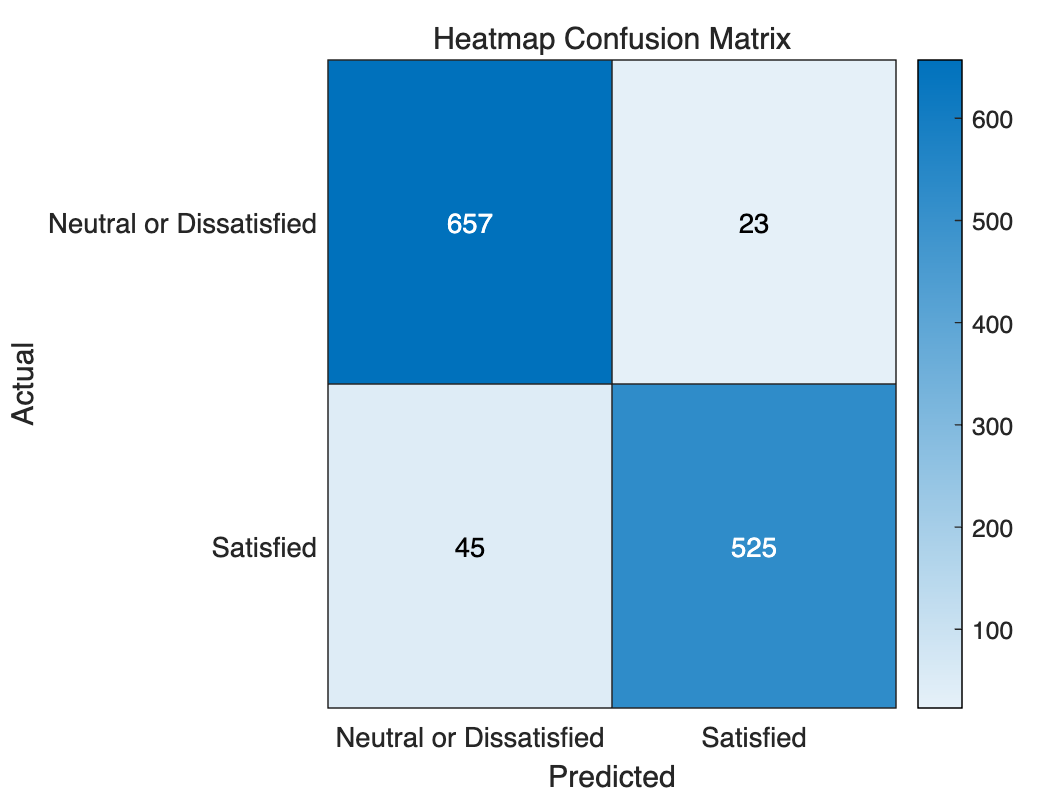

h.Title = 'Heatmap Confusion Matrix';
h.XLabel = 'Predicted';
h.YLabel = 'Actual';
h.XDisplayLabels = {'Neutral or Dissatisfied','Satisfied'};
h.YDisplayLabels = {'Neutral or Dissatisfied','Satisfied'};



% Show the accuracy
Accuracy = trace(Confusion_Matrix)/sum(Confusion_Matrix, 'all')

Accuracy = 0.9456


% Calcurate precision and recall
diagonal = diag(Confusion_Matrix)

diagonal =    657
   525


sum_rows = sum(Confusion_Matrix, 2)

sum_rows =    680
   570



precision = diagonal ./ sum_rows

precision =     0.9662
    0.9211


mean_precision = mean(precision)

mean_precision = 0.9436


sum_columns = sum(Confusion_Matrix, 1)

sum_columns =    702   548



recall = diagonal ./ sum_columns'

recall =     0.9359
    0.9580


mean_recall = mean(recall)

mean_recall = 0.9470


% Calcurate F1 score based upon precision and recall
F1_score = 2*((mean_precision*mean_recall)/(mean_precision+mean_recall))

F1_score = 0.9453